## Exercice 1

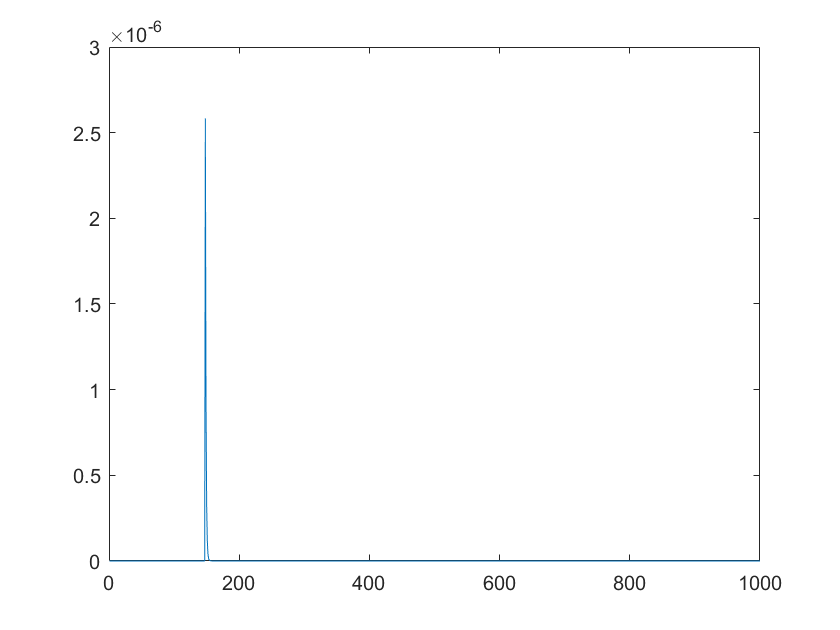

c=0.5;
Nx=1000;
dx=10/Nx;
dt=0.01;
Nt=T/dt;
T=4;
U=zeros(Nx,1);
beta=c*dt/dx;
A=matriceA(Nx,beta);
B=inv(A);
for i=1:Nx
    U(i,1)=exp(-(-5+dx*(i-1))^2);
end
for t=1:Nt-1
    U=[U,B.*U(:,t)];
    plot(U(:,t))
    pause(1)
end

## Exercice 4

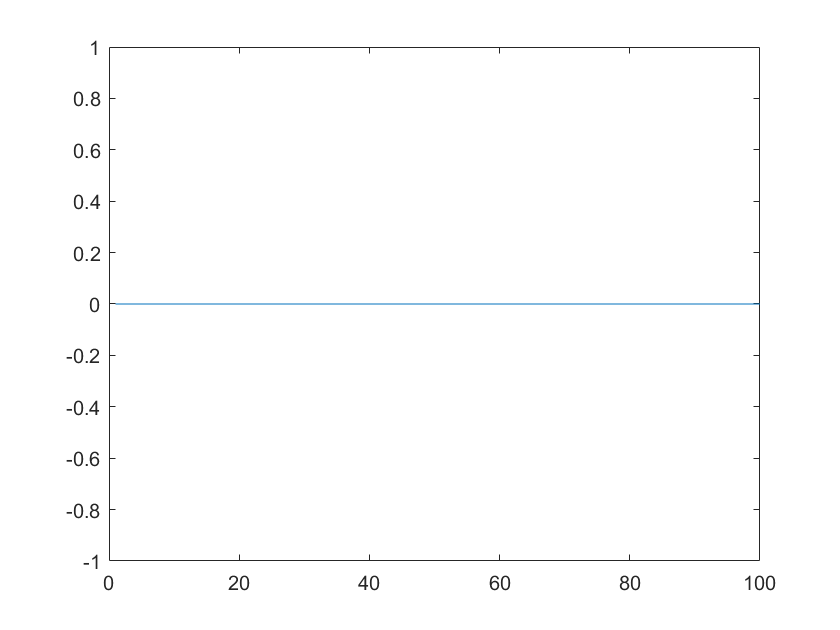

T=3/2;
dx=0.1;
dt=0.01;
Nx=10/dx;
Nt=T/dt;
beta=dt/dx;
U=((x.^2).*(1-x).^2.*(x>=0).*(x<=1))';
pas=(Nx+1)/Nx;
x=0:pas*dx:10;
for t=1:Nt
    A=eye(Nx)+2*beta*dt*t*(-diag(x)+diag(x(2:Nx),-1));
    U=[U,A.*U(:,t)];
    plot(U(:,t))
    pause(0.1)
end

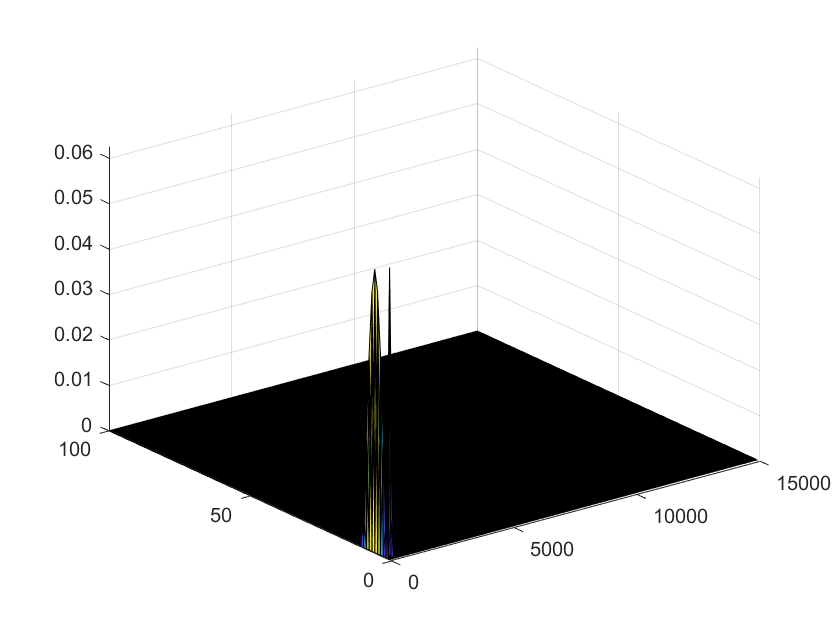

surf(U)

function A = matriceA(Nx,beta) 
un=ones(Nx-1,1);
A=(1+beta)*eye(Nx)-beta*diag(un,-1);
end